# Initialize

close all;
clear variables; 
global n_plot
init_FB();

### Observation bandwidth

f_min = 200e9; % lowest frequency
f_max = 460e9; % highest frequency
nF    = 1e4; %number of frequency samples
f     = linspace(f_min,f_max,nF); % frequency  

### Filter-bank properties

Qi          = Inf;%3000; %3300;%Inf; % It can be a vector
sep         = 1/4; %0.133;%0.1625;%1/4;%1/2;%3/4;
Ql_target   = 100;
ThruLineLosses = 0; 
S           = 1; % Oversampling

f0_min      = 220e9;
f0_max      = 2*f0_min;
nFilters    = floor( 1 + log10(f0_max / f0_min) / log10(1 + 1 ./ Ql_target ./ S) );

f0          = zeros(1,nFilters);
f0(1)       = f0_min;

for filter_i=2:nFilters
   f0(filter_i) = f0(filter_i-1) + f0(filter_i-1) * 1 ./ Ql_target ./ S;
end
f0 = sort(f0,'descend');

% TL-Impedances
Z0_KID      = 54.81;
Z0_thru     = 79.04;



singleFilterPlot = nFilters;

% SET SETTINGS
Settings.singleFilterPlot = nFilters; 
Settings.Z0_thru = Z0_thru;
Settings.Z0_KID = Z0_KID;
Settings.Qi = Qi;
Settings.ThruLineLosses = ThruLineLosses;
Settings.sep = sep;
Settings.f0 = f0;
Settings.Ql_target = Ql_target;

### Loop

n_loops = 5;

for iter = 1:n_loops
    n_plot = 0;



### Variances

    %% Ql %%
    Ql_sigma = 0.1; % Variance of Ql, normalized to 1
    
    %% f0 %%
    f0_sigma = 0;%0.27;% .* Ql_target ./ 500; % Relative variance of f0 (df), normalized to 1. 
    f0_drift = 0; % linear drift of f0
    f0_offset = 0; % additive offset of f0
    
    % Lower bound on Ql_scattered, based on analysis of Deshima II by Akira
    Ql_min_thresh = -1.5 .* Ql_target .* Ql_sigma;
    
    
    
    num_elem = 4; 
    Ql_variance = zeros(num_elem,nFilters);
    f0_variance = zeros(num_elem,nFilters);
    
    interFilterVariance = false;
    
    
    if interFilterVariance
        
%         Ql_sigma = Ql_sigma ./ sqrt(2);
%         f0_sigma = f0_sigma ./ sqrt(2);
    
        for i_elem = 1:num_elem %#ok<*UNRCH> 
            
            %%%% Scattered design parameters %%%%
            Ql_variance(i_elem,:) = Ql_target .* Ql_sigma .* randn(1,nFilters);
            Ql_variance(i_elem,Ql_variance(i_elem,:) < Ql_min_thresh) = Ql_min_thresh;
            df = f0 ./ Ql_target;
            f0_variance(i_elem,:) = df .* f0_sigma .* randn(1,nFilters);
        end
    else
        
        %%%% Scattered design parameters %%%%
        Ql_variance = repmat(Ql_target .* Ql_sigma .* randn(1,nFilters),4,1);
        Ql_variance(Ql_variance < Ql_min_thresh) = Ql_min_thresh;
        df = f0 ./ Ql_target;
        f0_variance = repmat(df .* f0_sigma .* randn(1,nFilters),4,1);
    end
    
    Settings.f0_variance = f0_variance;
    Settings.Ql_variance = Ql_variance;

# Filterbanks

## Directional filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceDirectionalFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 5.167097 seconds


Section took 5.306891 seconds


Section took 5.092811 seconds


Section took 5.260563 seconds


Section took 5.195455 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_dir(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.642418 seconds
Usable Spectral Fraction = 0.94
Section took 0.522353 seconds


Section took 1.503483 seconds
Usable Spectral Fraction = 0.96
Section took 0.507800 seconds


Section took 1.553958 seconds
Usable Spectral Fraction = 0.94
Section took 0.504799 seconds


Section took 1.678544 seconds
Usable Spectral Fraction = 0.93
Section took 0.505046 seconds


Section took 1.516224 seconds
Usable Spectral Fraction = 0.93
Section took 0.538464 seconds


    % % % showDimensions(f,f0,l_thru)

## Reflector filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceReflectorFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 3.039615 seconds


Section took 2.933051 seconds


Section took 2.887163 seconds


Section took 3.095875 seconds


Section took 2.984251 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_refl(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.400434 seconds
Usable Spectral Fraction = 0.96
Section took 0.494105 seconds


Section took 1.325147 seconds
Usable Spectral Fraction = 0.98
Section took 0.504887 seconds


Section took 1.363218 seconds
Usable Spectral Fraction = 0.96
Section took 0.523066 seconds


Section took 1.505589 seconds
Usable Spectral Fraction = 0.94
Section took 0.517415 seconds


Section took 1.564718 seconds
Usable Spectral Fraction = 0.95
Section took 0.556623 seconds


    % % % % showDimensions(f,f0,l_thru)

## Manifold filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceManifoldFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 2.247737 seconds


Section took 2.265643 seconds


Section took 2.201604 seconds


Section took 2.267147 seconds


Section took 2.379688 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_man(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.343134 seconds
Usable Spectral Fraction = 0.86
Section took 0.478411 seconds


Section took 1.527516 seconds
Usable Spectral Fraction = 0.88
Section took 0.523724 seconds


Section took 1.350993 seconds
Usable Spectral Fraction = 0.86
Section took 0.482483 seconds


Section took 1.343584 seconds
Usable Spectral Fraction = 0.86
Section took 0.489253 seconds


Section took 1.488342 seconds
Usable Spectral Fraction = 0.85
Section took 0.569396 seconds


    % % showDimensions(f,f0,l_thru)
    
end

## Plotting

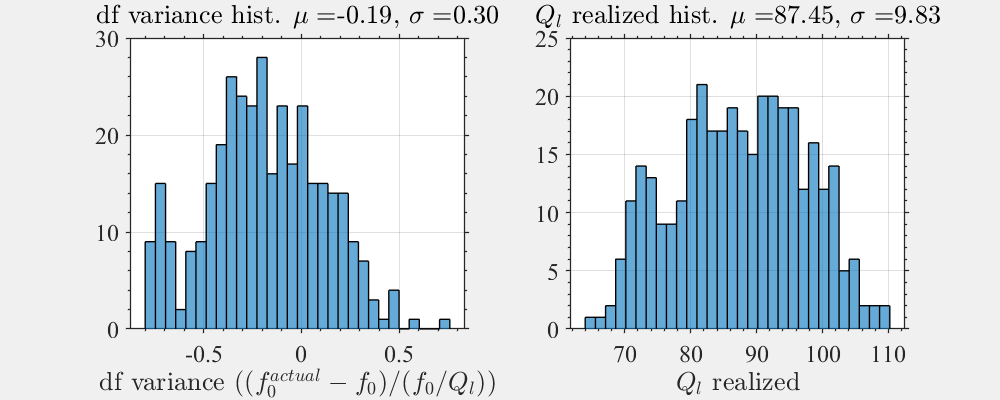

close all; 
clear functions; %#ok<CLFUNC>
n_plot = 1;
showFilterBank(f,Data_dir); 
showMetrics(f,Ql_target,Data_dir);

Stats_dir = calcStatistics(f0,Ql_target,Data_dir);
showStatistics(f,Data_dir,Stats_dir);

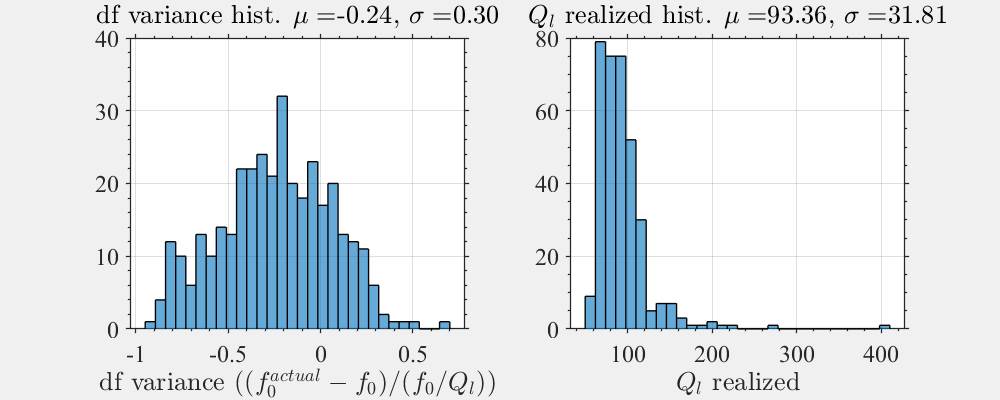


n_plot = 2;
showFilterBank(f,Data_refl);
showMetrics(f,Ql_target,Data_refl);

Stats_refl = calcStatistics(f0,Ql_target,Data_refl);
showStatistics(f,Data_refl,Stats_refl);


n_plot = 3;
showFilterBank(f,Data_man);

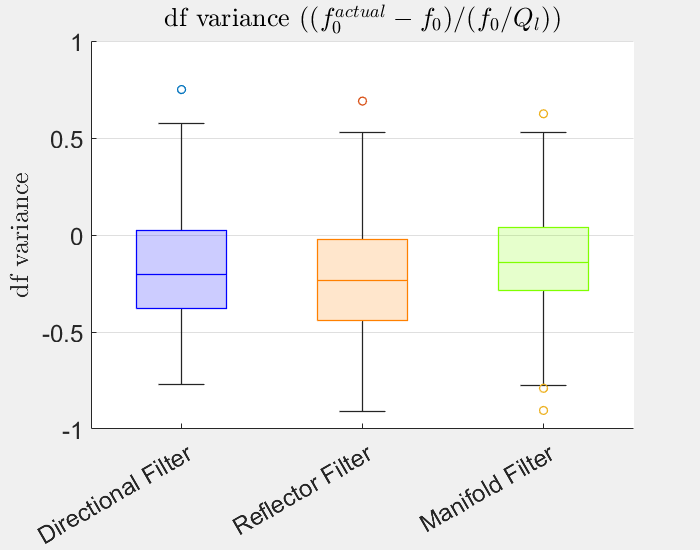

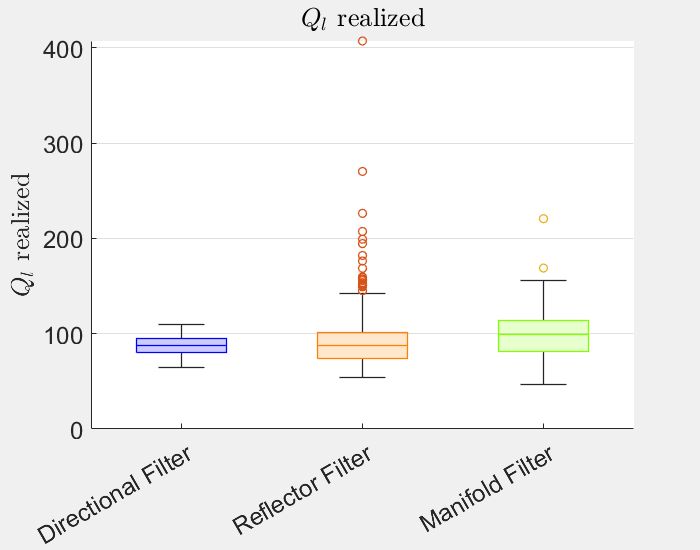

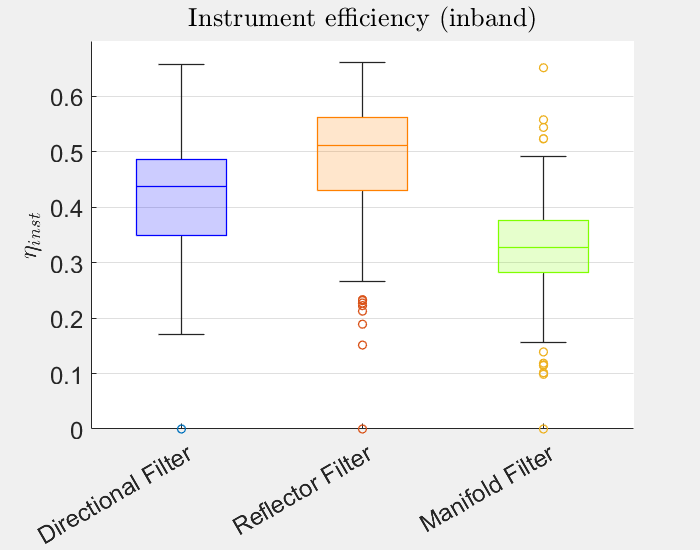

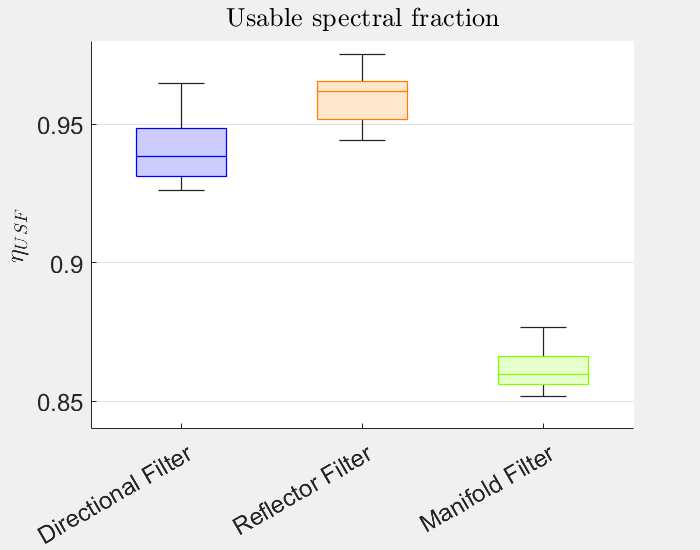

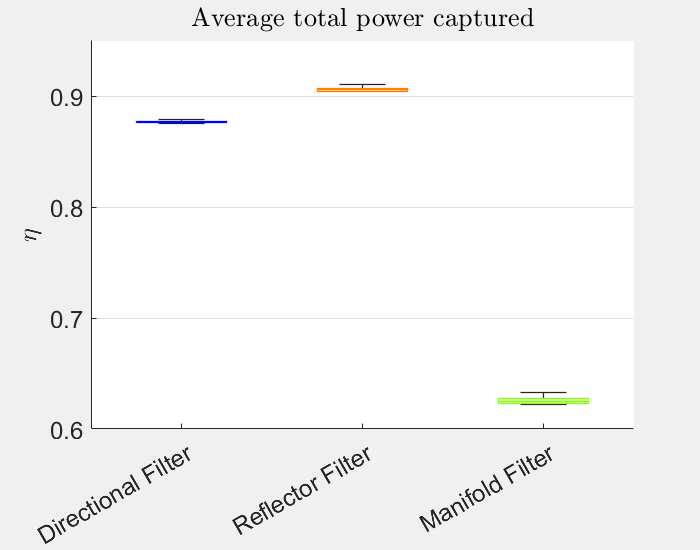

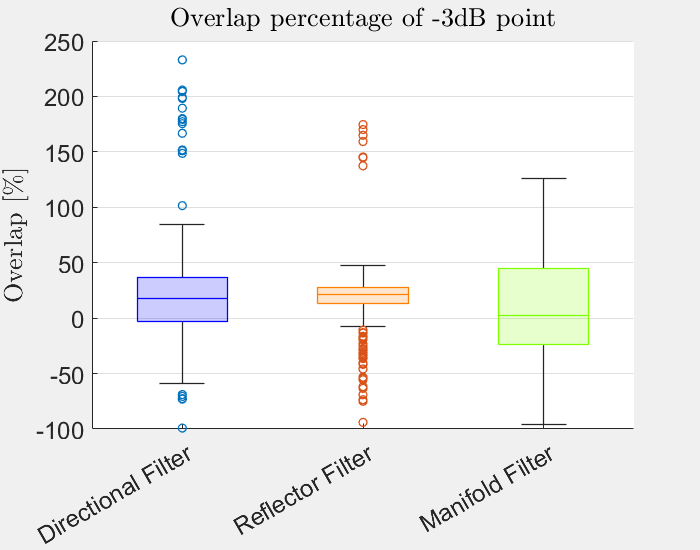

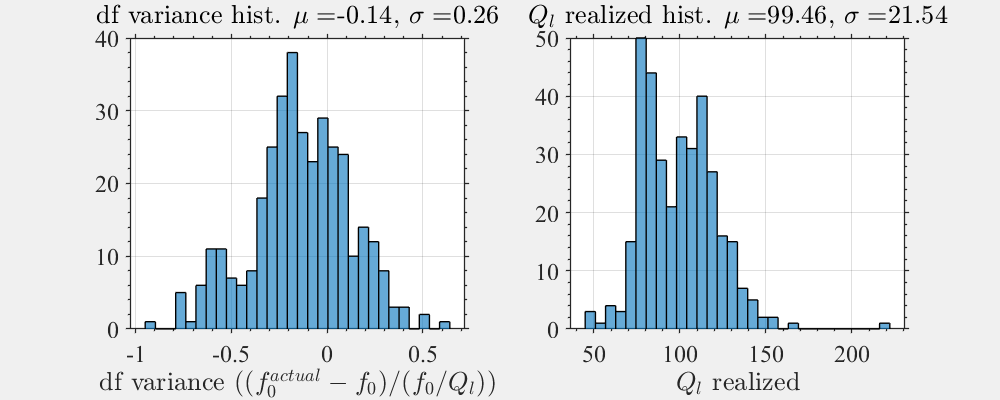

showMetrics(f,Ql_target,Data_man);

Stats_man = calcStatistics(f0,Ql_target,Data_man);
showStatistics(f,Data_man,Stats_man);

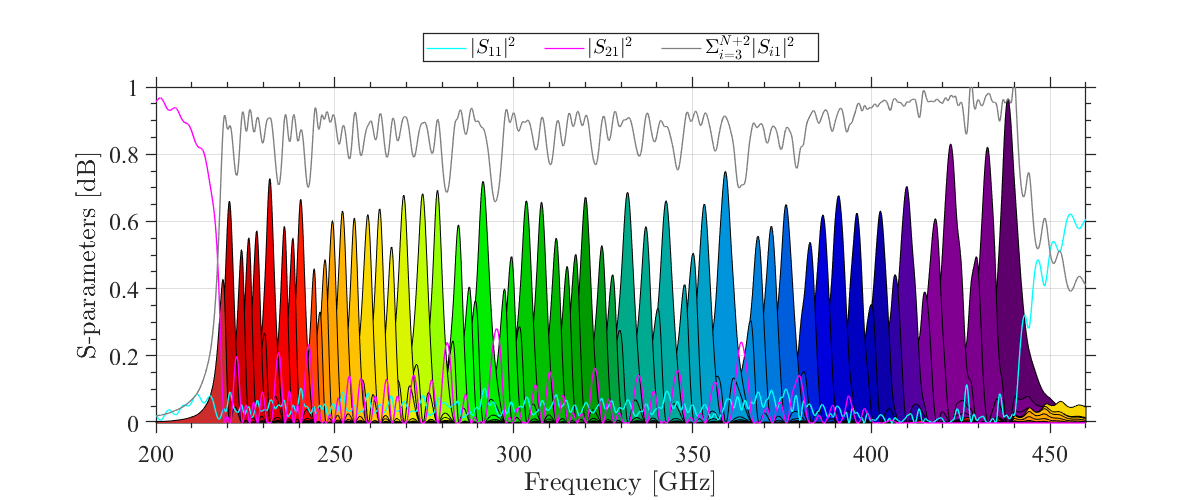

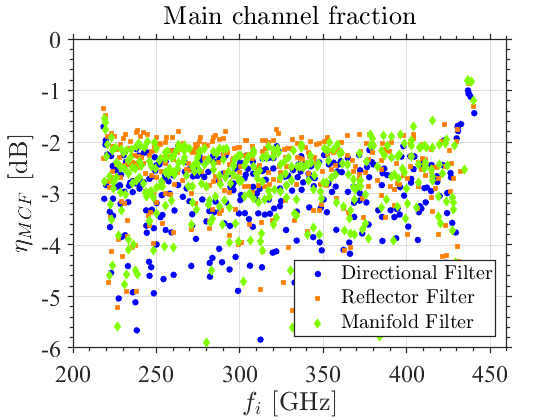

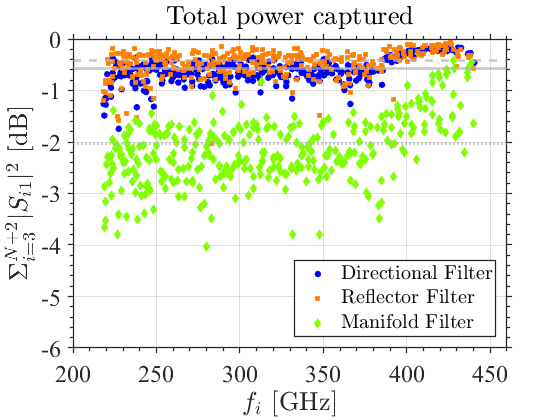

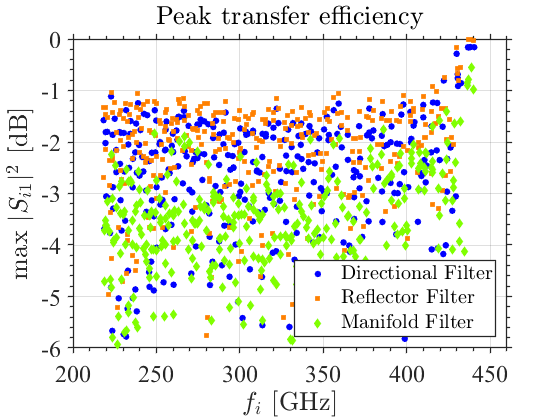

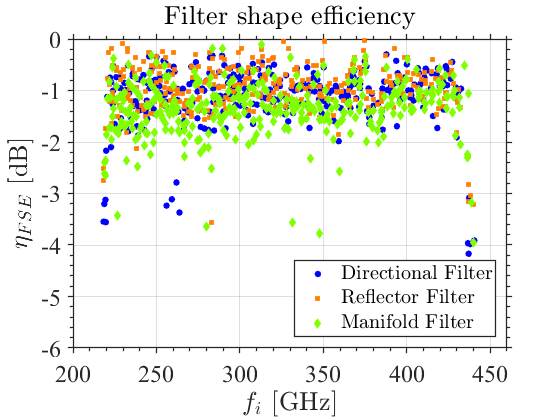

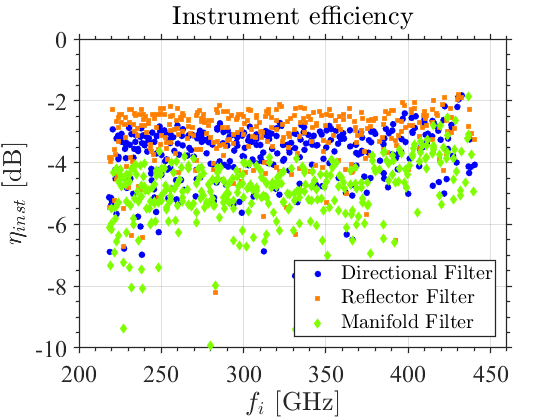

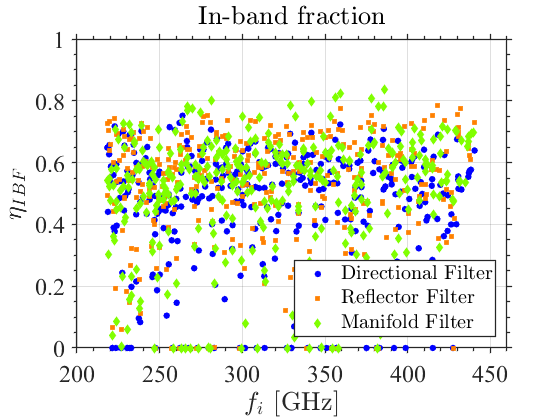

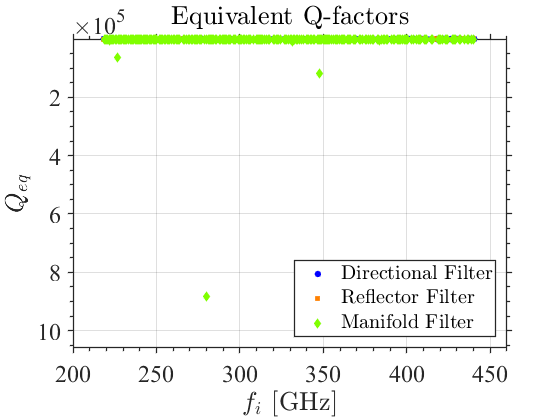



formatPlotting();